 
clear
clc
tic
marketData = MarketData;
marketData = marketData.loadSymbolMCapRef;

toc

Elapsed time is 0.642158 seconds.


 
tic
marketData = marketData.loadDataFromYahoo
toc

 
tic
marketData = marketData.loadDataFromSpreadsheet;
toc


 
tic
marketData = marketData.loadDataFromMatFile;
toc

Elapsed time is 0.140204 seconds.


 
tic
marketData = marketData.cleanData;
toc

Elapsed time is 58.691141 seconds.


 
tic
marketData.saveDataToSpreadsheet;
toc

 
tic
marketData.saveDataToMatFile;
toc


 
% prepare the data
marketData

marketData =   MarketData with properties:

                 yahooData_fileName: "DataInput\Symbols_MarketCap_MarketCapCategoryRange.xlsx"
       yahooData_symMktCapSheetName: "SymbolsMarketCapReference"
    yahooData_mktCapCategRangeSheet: "MarketCap_Category_Range"
                          startDate: 01-Jan-2018
                            endDate: 19-Feb-2022
                           interval: "1d"
                           maxRetry: 3
           spreadhseetData_filename: "PriceVolumeInput.xlsx"
               spreadhseetData_path: "C:\Users\kikim\OneDrive\Documents\MATLAB_Projects\BackTradeModule_Project\DataInput"
     spreadhseetData_openPriceSheet: "openPrice"
      spreadhseetData_lowPriceSheet: "lowPrice"
     spreadhseetData_highPriceSheet: "highPrice"
    spreadhseetData_closePriceSheet: "closePrice"
        spreadhseetData_volumeSheet: "volume"
     spreadhseetData_IndexIHSGSheet: "IndexIHSG"
           


dataInput.openPrice = marketData.openPrice;
dataInput.highPrice = marketData.highPrice;
dataInput.lowPrice = marketData.lowPrice;
dataInput.closePrice = marketData.closePrice;
dataInput.volume = marketData.volume;

 
% generate tradingSignal
tradingSignalParameter =[               % open the array
                            80        % liquidityVolumeMALookback = paramInput(1);
                            0.1        % liquidityVolumeMAThreshold = paramInput(2);
                            3       %liquidityVolumeMANDayBuffer = paramInput(3) 
                            80        % liquidityValueMALookback  = paramInput(4);
                            0.1        % liquidityValueeMAThreshold  = paramInput(5);
                            3       %liquidityValueMANDayBuffer = paramInput(6)
                            20        % liquidityNDayVolumeValueBuffer = paramInput(7);
                            20        % momentumPriceMALookback = paramInput(8);
                            1.2        % momentumPriceMAToCloseThreshold = paramInput(9);
                            1        % momentumPriceRetLowToCloseLookback = paramInput(10);
                            0.05        % momentumPriceRetLowToCloseThreshold = paramInput(11);
                            3        % momentumPriceRetLowToCloseNDayBuffer = paramInput(12);
                            5        % liquidityMomentumSignalBuffer = paramInput(13);
                            5        % cutLossHighToCloseNDayLookback = paramInput(14);
                            0.05        % cutLossHighToCloseMaxPct = paramInput(15);
                            1        % nDayBackShift = paramInput(16);
                                ] ;  % close the array


tradingSignalOut = generateTradingSignalFcn (dataInput, tradingSignalParameter)

tradingSignalOut = 1041×709 timetable
       Time       AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    <s

% % inspect tradingSignal
% tradingSignalVar = tradingSignalOut.Variables

tradingSignalVar =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0

% a = sum(tradingSignalVar,2)

a =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% b = sum(a,1)

b = 10427

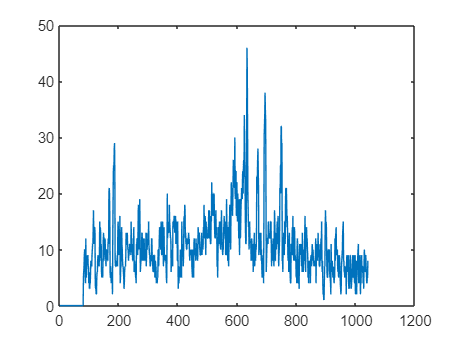

% plot(a)

 
% backtest the signal
dataStructInput = dataInput;
tradingSignal = tradingSignalOut;
tradingCost = [0.15/100, 0.25/100];
maxCapAllocation = 0.2;

resultStruct = btEngineVectorizedFcn (dataStructInput, tradingSignal, tradingCost, maxCapAllocation)

resultStruct = struct with fields:
    dailyNetRetPortfolioTT: [1041×1 timetable]
    equityCurvePortfolioTT: [1041×1 timetable]
       dailyNetRetPerSymTT: [1041×709 timetable]
       equityCurvePerSymTT: [1041×709 timetable]
              totalBuyCost: 0.0843
             totalSellCost: 0.1382
         totalSlippageCost: -0.1820


% optimize the parameter


% walk forwad set up


% do walk forwad

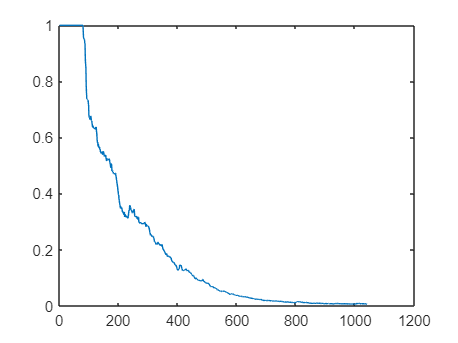

% analyze the result
% equityCurveTT = resultStruct.equityCurvePortfolioTT.Variables;
% plot(resultStruct.equityCurvePortfolioTT.Variables);

% cumRet = equityCurveTT (end) / equityCurveTT (1) -1

cumRet = -0.9946

% maxDD = maxdrawdown(equityCurveTT)

maxDD = 0.9946

% data for generateTradingSignalFcn 

